# Getting Started with CiCueTea

CiCueTea is a real-time, invertible Constant-Q Transform (CQT) engine based on nonstationary Gabor frames (NSGF). This example computes an ERB-based and a CQT-based transform of a short audio clip and visualizes both the analysis frame and the resulting time-frequency representation.

Requires MATLAB's Signal Processing Toolbox.

## Load example audio

Handel's Messiah, resampled to the transform's target sample rate.

load handel.mat
fs = 48000;
x = resample(y, fs, Fs);

## Set analysis parameters

freq2erb is example-only (Psychoacoustics/, alongside this script) — the VQT constructor takes any frequency-warping function; ERB is just one.

addpath(fullfile(fileparts(mfilename('fullpath')), 'Psychoacoustics'));


nSamps = length(x);
fracCQT = 1;                     % 1 band per octave
fracERB = 1/2;                   % 1 band per half-ERB
fMap = @freq2erb;                % Frequency mapping for the ERB transform
fMin = 100;
fMax = 10000;
fRef = 1000;

## Initialize the ERB-based and CQT-based transforms

sERB = nsgfVQTInit("dense", fs, nSamps, fMap, fracCQT, fMin, fMax, fRef);
sCQT = nsgfVQTInit("dense", fs, nSamps, @log2, fracERB, fMin, fMax, fRef);

## Compute the transforms

XERB = nsgfCQT(x, sERB);
XCQT = nsgfCQT(x, sCQT);

## Plot the analysis frames

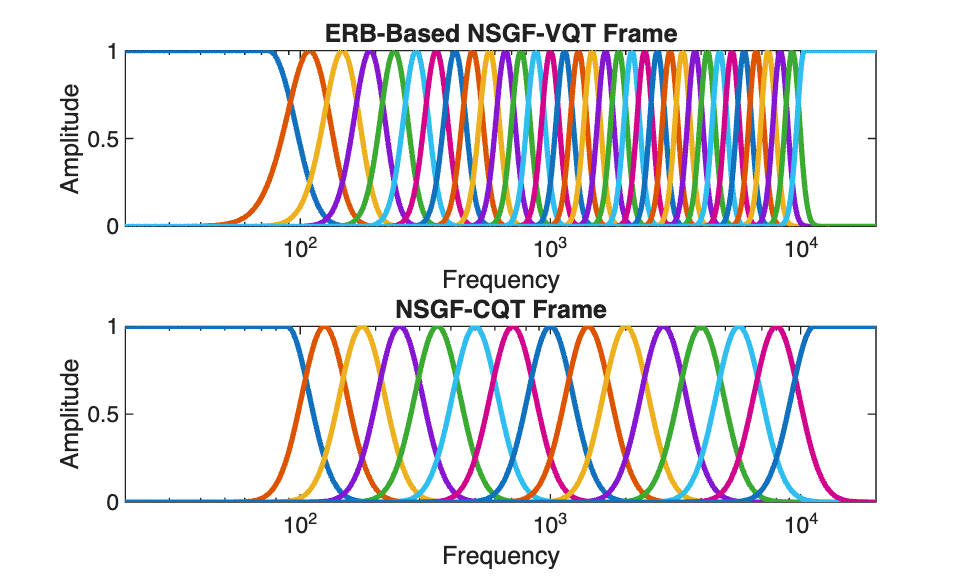

figure;
subplot(2, 1, 1)
semilogx(sERB.fax, sERB.g, "LineWidth", 2);
xlim([2e1, 2e4])
xlabel("Frequency");
ylabel("Amplitude");
title("ERB-Based NSGF-VQT Frame")

subplot(2, 1, 2)
semilogx(sCQT.fax, sCQT.g, "LineWidth", 2);
xlim([2e1, 2e4])
xlabel("Frequency");
ylabel("Amplitude");
title("NSGF-CQT Frame")

## Plot the time-frequency representations

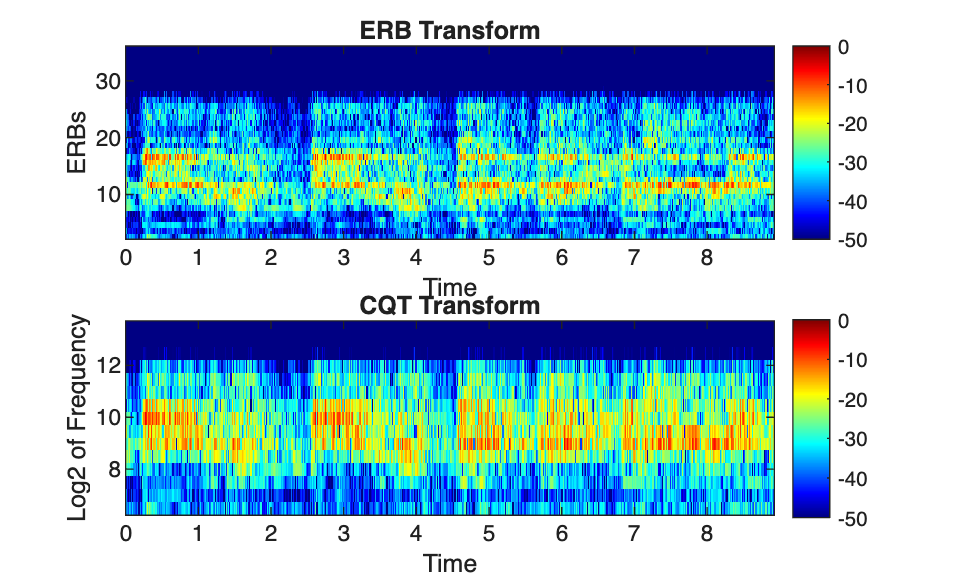

tax = sCQT.tax;
tax = tax - tax(1);
range = [-50, 0];

figure;
subplot(2, 1, 1)
imagesc(tax, sERB.bax, dB(XERB).');
colormap jet
colorbar
set(gca, "CLim", range)
set(gca, "YDir", "normal");
title("ERB Transform");
xlabel("Time");
ylabel("ERBs");

subplot(2, 1, 2)
imagesc(tax, sCQT.bax, dB(XCQT).');
colormap jet
colorbar
set(gca, "CLim", range)
set(gca, "YDir", "normal");
title("CQT Transform");
xlabel("Time");
ylabel("Log2 of Frequency");